# Van der Pol Oscillator - Parameter Sweep

This is a parameter sweep study of the van der Pol equation, a classic system to challenge stiff solvers. 


$$\alpha \;\ddot{y_1 } -\beta \;\left(1-y_1^2 \right)\dot{y_1 } +y_1 =0$$


This system can be written as a first-order ODE by making the substitution $\dot{y_1 } =\nu y_2$. The resulting system is:


$$\dot{y_1 } =\nu \;y_2$$



$$\dot{y_2 } =\mu \left(1-y_1^2 \right)y_2 -y_1$$


The goal is to find the mean period of $y_2$ for different values of the parameters $\mu$ and $\nu$. 

Additional info on the ODE problem can be found on: [Van der Pol Equation](https://www.mathworks.com/help/releases/R2017a/matlab/math/solve-nonstiff-odes.html)

## Problem Setup

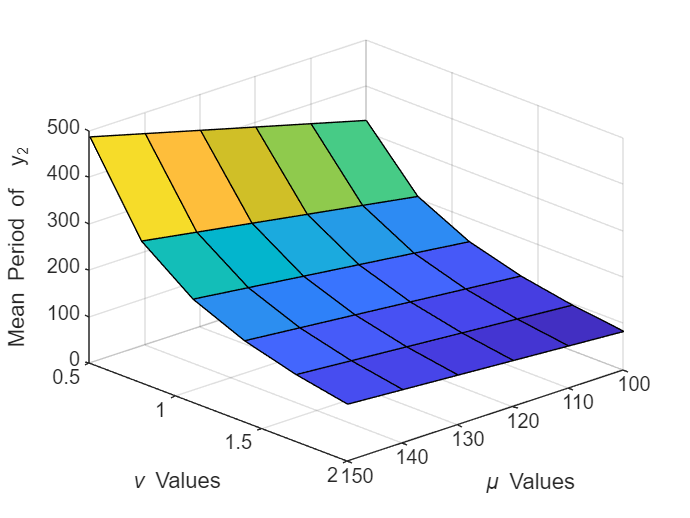

gSize = 6; % Grid size

x = linspace(100, 150, gSize); % Parameter mu values
y = linspace(0.5, 2, gSize); % Parameter nu values
[X,Y] = meshgrid(x,y);
Z = nan(size(X));

fig1 = figure(1);
c = surf(X, Y, Z);
xlabel('\mu Values','Interpreter','Tex')
ylabel('\nu Values','Interpreter','Tex')
zlabel('Mean Period of  y_2')
view(137, 30)
axis([100 150 0.5 2 0 500]);

D = parallel.pool.DataQueue;
D.afterEach(@(x) updateSurface(c, x));

## Solve Equation

t0 = tic;
parfor ii = 1:numel(X)
    
    [t, yy] = solveVdp(X(ii), Y(ii));
    l = islocalmax(yy(:, 2));
    Z(ii) = mean(diff(t(l)));
    send(D, [ii Z(ii)]);
    
end
CompTime = toc(t0)

CompTime = 2.4008

## Helper Functions

function [t, y] = solveVdp(mu, nu)
f = @(~,y) [nu*y(2); mu*(1-y(1)^2)*y(2)-y(1)];
[t,y] = ode23s(f,[0 20*mu],[2 0]);
end

*Copyright 2023 The MathWorks, Inc.*